fs=20

fs = 20

N_samples=2000

N_samples = 2000

t=linspace(0,N_samples/fs,N_samples)

t =          0    0.0500    0.1001    0.1501    0.2001    0.2501    0.3002    0.3502    0.4002    0.4502    0.5003    0.5503    0.6003    0.6503    0.7004    0.7504    0.8004    0.8504    0.9005    0.9505    1.0005    1.0505    1.1006    1.1506    1.2006    1.2506    1.3007    1.3507    1.4007    1.4507    1.5008    1.5508    1.6008    1.6508    1.7009    1.7509    1.8009    1.8509    1.9010    1.9510    2.0010    2.0510    2.1011    2.1511    2.2011    2.2511    2.3012    2.3512    2.4012    2.4512


a=sin(2*pi*t*0.1)+0.5*cos(2*pi*t*0.2)+0.25*sin(2*pi*t*0.05)

a =     0.5000    0.5344    0.5667    0.5971    0.6254    0.6516    0.6759    0.6981    0.7183    0.7365    0.7527    0.7671    0.7795    0.7902    0.7991    0.8063    0.8119    0.8159    0.8185    0.8197    0.8195    0.8182    0.8158    0.8123    0.8079    0.8027    0.7968    0.7902    0.7832    0.7757    0.7679    0.7599    0.7517    0.7436    0.7355    0.7276    0.7199    0.7126    0.7057    0.6993    0.6934    0.6881    0.6836    0.6797    0.6767    0.6745    0.6731    0.6727    0.6731    0.6745


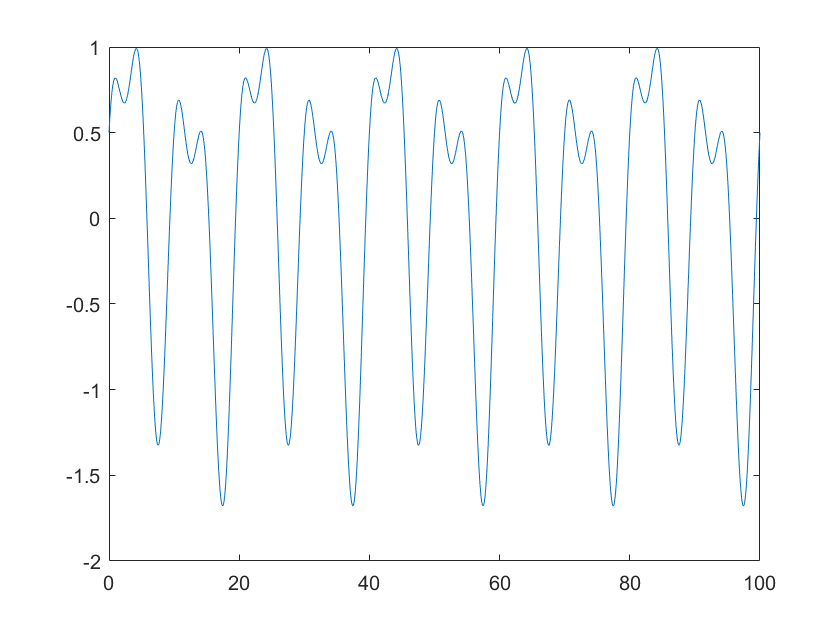

plot(t,a)

%%https://github.com/jlpscampos/Ensemble_EMD_significance_test
[imf,residual,info] = emd(a,'Interpolation','pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.13415   |  SiftMaxRelativeTolerance
      2      |        1     |     0.061815   |  SiftMaxRelativeTolerance
      3      |        2     |     0.011538   |  SiftMaxRelativeTolerance
      4      |        3     |     0.079803   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1817   |  SiftMaxRelativeTolerance
Decomposition stopped because the number of extrema in the residual signal is less than the 'MaxNumExtrema' value.


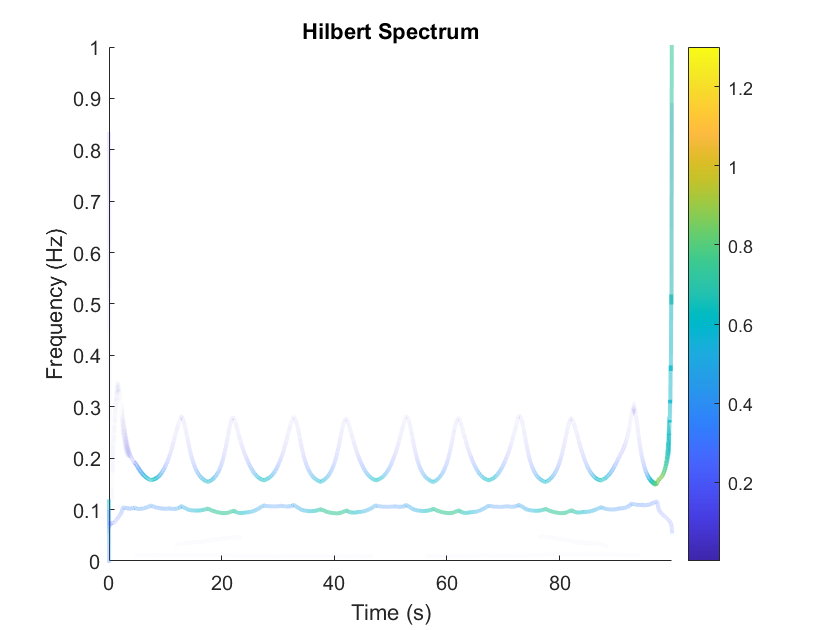

imf=EMD_timeseries(t,a,'pchip');
emd(a)
[hs,f,t,imfinsf,imfinse] =hht(imf,fs);
hht(imf,fs)
ylim([0 1])